desktop = com.mathworks.mde.desk.MLDesktop.getInstance;
desktop.restoreLayout('Default');  


[y, fs] = audioread('RagaDownloads\Abhogi\vocals_AjoyC_SilRem.wav')

y =          0    0.0000
         0   -0.0001
         0    0.0002
         0   -0.0002
   -0.0000    0.0001
    0.0001   -0.0000
   -0.0001   -0.0000
    0.0001    0.0001
   -0.0001   -0.0000
    0.0001         0


fs = 44100

y = y(:,1); %select 1 channel : mono


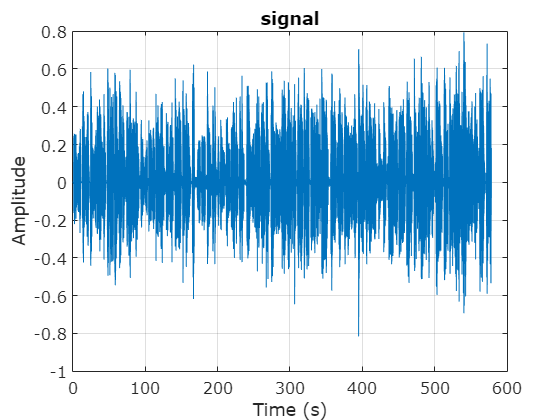

N = length(y);
t = (0:N-1)/fs;
plot(t,y)
grid on
set(gca, 'FontName','Verdana','FontSize', 12)
xlabel('Time (s)')
ylabel('Amplitude')
title("signal")

%S = audioplayer(x1, fs);
%S.play();

%sound(x1,fs)

maxValue = max(x)
%S.pause();

ydb = mag2db(y);
plot(t,ydb)

% %sound(x1,fs)
% new_data = zeros(N,1);
% for i = 1 : N
%     if (ydb )


%clear sound; %to stop sound wav thats playing

%test reading concatenated mp3
figure;
[y, fs] = audioread('D:\MatlabData\HMD\audio_flat\Abhogi\Bonus_Track_b63f8746-775e-447b-8bd5-1f32c4ef0b44.mp3')

y =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 44100

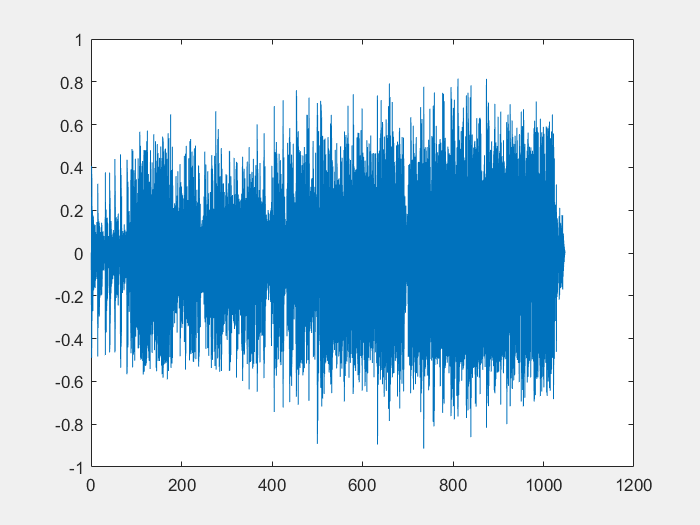

y = y(:,1); %select 1 channel : mono
N = length(y);
t = (0:N-1)/fs;
plot(t,y);
uicontrol('Visible','off')

figure;
[y2, fs] = audioread('D:\MatlabData\HMD\audio_flat\Abhogi\Raag_Abhogi_a01ac873-dff4-420f-9fd8-490dd87c58e9.mp3');
y2 = y2(:,1) %select 1 channel : mono

y2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


N = length(y2);
t = (0:N-1)/fs;
plot(t,y2);
 uicontrol('Visible','off')

info = audioinfo(['D:\MatlabData\HMD\audio_flat\Abhogi\output.mp3'])

info = struct with fields:
             Filename: 'D:\MatlabData\HMD\audio_flat\Abhogi\output.mp3'
    CompressionMethod: 'MP3'
          NumChannels: 2
           SampleRate: 44100
         TotalSamples: 523845504
             Duration: 1.1879e+04
                Title: 'Bonus Track'
              Comment: []
               Artist: 'Rashid Khan'
              BitRate: 194.1120


 %use VLC to view large audio files. MAtlab runs out of memory for 3hr long
 %mp3 file
 
 [y3, fs] = audioread('D:\MatlabData\HMD\audio_flat\Abhogi\abhogi_spleeter\Abhogi_concatenated\vocals.wav');
y3 = y3(:,1) %select 1 channel : mono

y3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


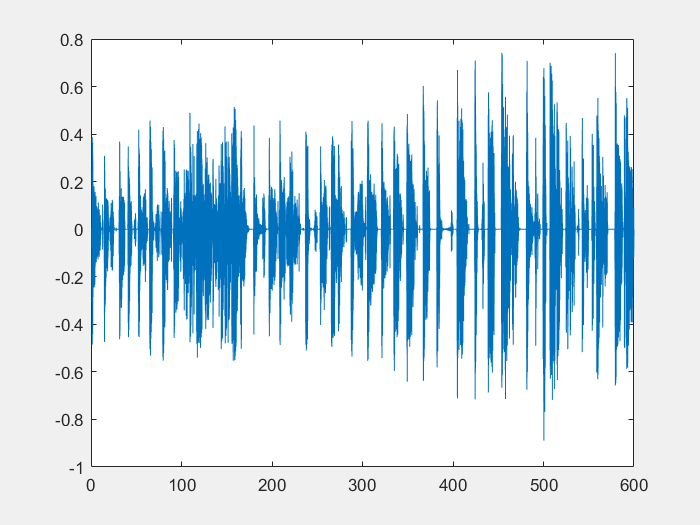

N = length(y3);
t = (0:N-1)/fs;
plot(t,y3);
 uicontrol('Visible','off')

% spectrogram for 1 channel
%s = spectrogram(x,window,noverlap,nfft) uses nfft sampling points to calculate the discrete Fourier transform.
% returns the short-time Fourier transform of the input signal, x. 
% Each column of s contains an estimate of the short-term, 
% time-localized frequency content of x.

% Using MATLAB's spectrogram
% 
% The syntax is spectrogram(x,window,overlap,NFFT,fs)
% 
% where
% 
% x
% is your entire data vector
% window 
% 
% is your window function. 
% If you enter just a number, say W (must be integer), 
% then MATLAB chops up your data into chunks of W samples each and forms the spectrogram from it. 
% This is equivalent to using a rectangular window of length W samples. 
% If you want to use a different window, provide hann(W) or whatever window you choose.
% overlap
%  is the number of samples that you need to overlap. So, if you need 50% overlap, this value should be W/2. 
% Use floor(W/2) or ceil(W/2) if W can take odd values. This is just an integer.
% NFFT 
% is the FFT length
% fs is the sampling frequency of your data vector.
%You can leave this empty, and MATLAB plots the figure in terms of normalized frequencies and the time axis as simply the data chunk index. 
% If you enter it, MATLAB scales the axis accordingly.


s = spectrogram(y,1024,512,1024)

s = 	1.0e+02 *

  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0000 - 0.0000i   0.0000 + 0.

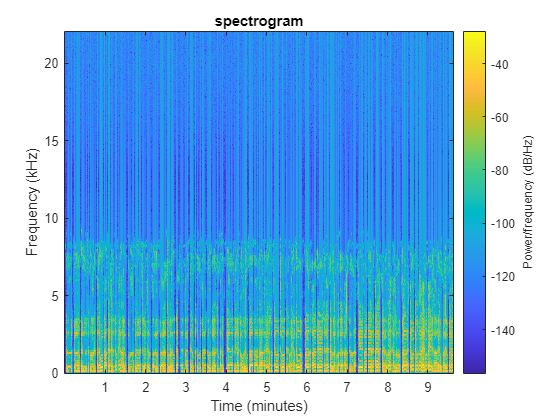

spectrogram(y,1024,512,1024,fs,'yaxis')
%since fs is 44.1 Khz y axis is 22KHz range
title("spectrogram")

% mel spectrogram
melSpectrogram(y,fs)
title("Melspectrogram")
[S,F,T]=melSpectrogram(y,fs);

[audioIn,fs] = audioread('FunkyDrums-44p1-stereo-25secs.mp3');
fs
sound(audioIn,fs)
N = length(audioIn);
t = (0:N-1)/fs;
plot(t,audioIn)
spectrogram(audioIn(:,1),1024,512,1024,fs,'yaxis')
%spectrogram(audioIn(:,1),fs,'yaxis')
title("Spectrogram")
melSpectrogram(audioIn,fs)
title("Melspectrogram")
melSpectrogram(audioIn,fs, ...
                   'Window',hann(2048,'periodic'), ...
                   'OverlapLength',1024, ...
                   'FFTLength',4096, ...
                   'NumBands',64, ...
                   'FrequencyRange',[62.5,8e3]);
title("Melspectrogram")


% PERIODOGRAM
w = hanning(N,'periodic');
periodogram(audioIn(:,1),w,N,fs,'power')

% HISTOGRAM
histogram(audioIn)

status = system('notepad &')

status = 0

command = 'cd';
[status,cmdout] = system(command)

status = 0

cmdout =     'G:\My Drive\MATLAB\Audio
     '
